## 1.- Grafique la señal x(t) usando un periodo de tiempo cuasi-continuo a fin de simular la señal analógica

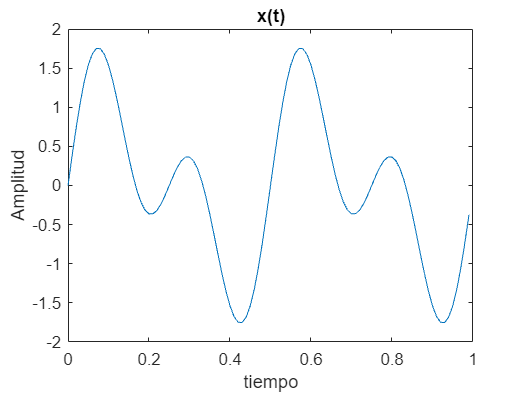

Fs = 100;
t = 0:1/Fs:1-1/Fs;
x = sin(4*pi*t)+sin(8*pi*t);
plot(t,x)
title("x(t)")
xlabel("tiempo")
ylabel("Amplitud")

## 2. Simule el muestreo de la señal a 10 Hz

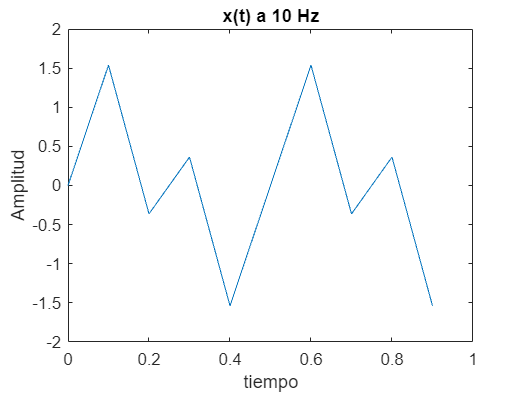

Fs = 10;
t = 0:1/Fs:1-1/Fs;
x = sin(4*pi*t)+sin(8*pi*t);
plot(t,x)
title("x(t) a 10 Hz")
xlabel("tiempo")
ylabel("Amplitud")

## 3.- Función de interpolación

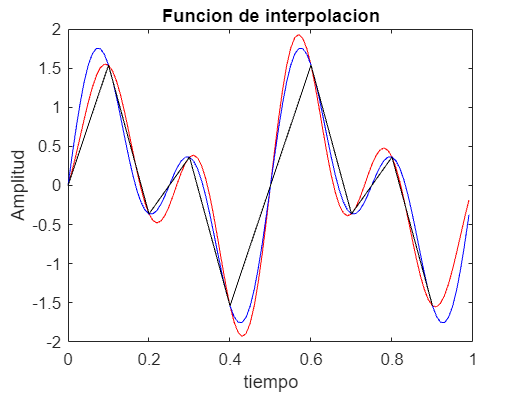

Fs = 10; 
t = 0:1/100:1-1/100; %Tiempo cuasi-continuo
t2 = 0:1/Fs:1-1/Fs; %10 Hz
suma = zeros(1,100);
x2 = sin(4*pi*t)+sin(8*pi*t);
x3 = sin(4*pi*t2)+sin(8*pi*t2);
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(4*pi*(i/Fs)) + sin (8*pi*(i/Fs)); 
   h = t -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot(t,suma,"red")
hold on;
plot(t,x2,"blue")
plot(t2,x3,"black")
title("Funcion de interpolacion")
xlabel("tiempo")
ylabel("Amplitud")
hold off;

## 4. Onda sinusoidal

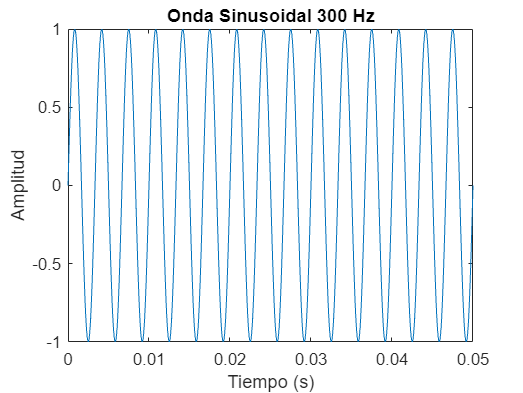

% Definir parámetros de la onda sinusoidal
Fs1 = 16000;
frecuencia = 300;       % Frecuencia en Hz
t1 = 0:1/Fs1:.05; % Muestras a 800Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 300 Hz');

## Interpolación

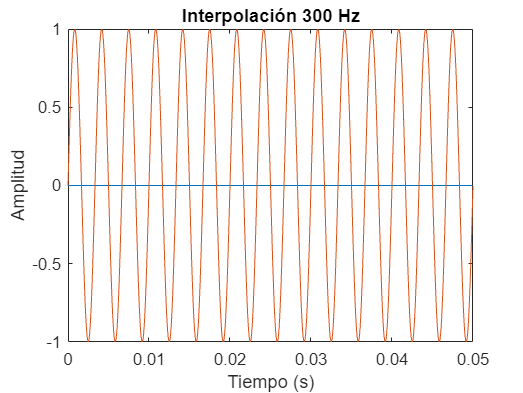

Fs =200; 
suma = zeros(1,801);
frecuencia = 300; 
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on;
plot(t1,senal)
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 300 Hz');
hold off;

## 5. Ondas sinusoidales

## a) 125 Hz

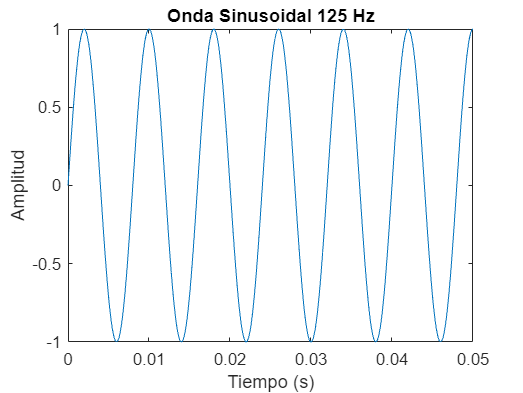

% Definir parámetros de la onda sinusoidal
frecuencia = 125;       % Frecuencia en Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 125 Hz');

## Interpolacion

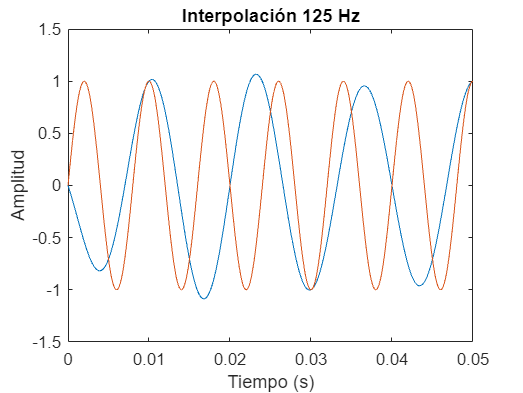

Fs = 200; 
suma = zeros(1,801);
frecuencia = 125; 
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on;
plot(t1,senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 125 Hz');
hold off;

## b) 215 Hz

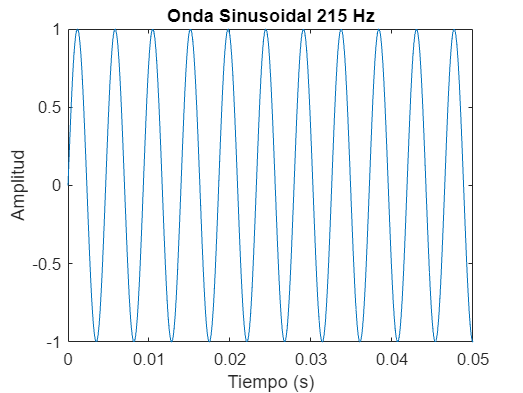

% Definir parámetros de la onda sinusoidal
frecuencia = 215;       % Frecuencia en Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 215 Hz');

## Interpolación

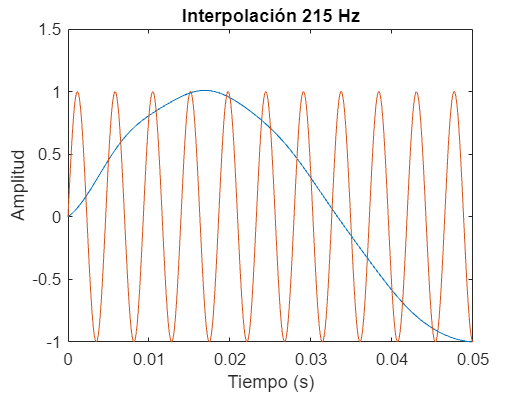

Fs = 200; 
suma = zeros(1,801);
frecuencia = 215; 
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on; 
plot(t1,senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 215 Hz');
hold off;

## c) 305 Hz

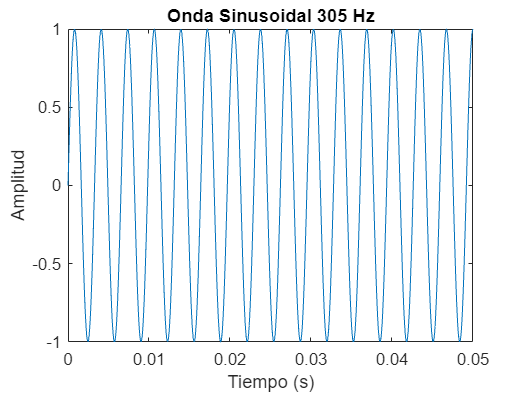

% Definir parámetros de la onda sinusoidal
frecuencia = 305;       % Frecuencia en Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 305 Hz');

## Interpolación

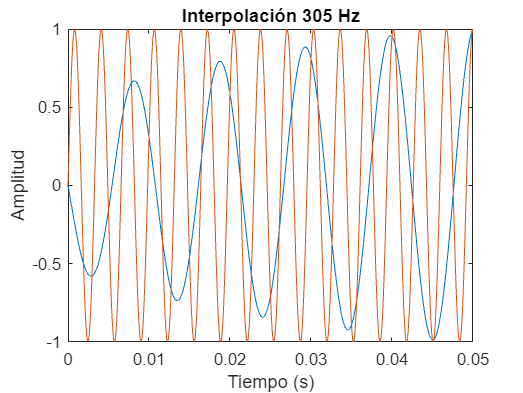

Fs = 200;
suma = zeros(1,801);
frecuencia = 305;
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on; 
plot(t1,senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 305 Hz');
hold off;

## d) 395 Hz

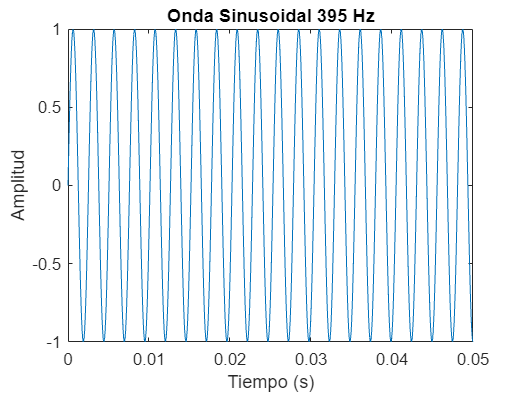

% Definir parámetros de la onda sinusoidal
frecuencia = 395;       % Frecuencia en Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 395 Hz');

## Interpolación

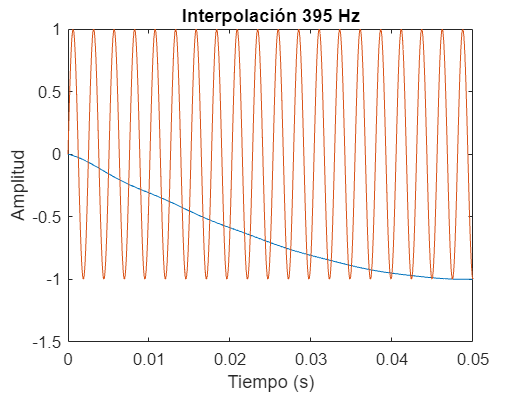

Fs = 200; 
suma = zeros(1,801);
frecuencia = 395; 
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on; 
plot(t1,senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 395 Hz');
hold off;

## e) 500Hz

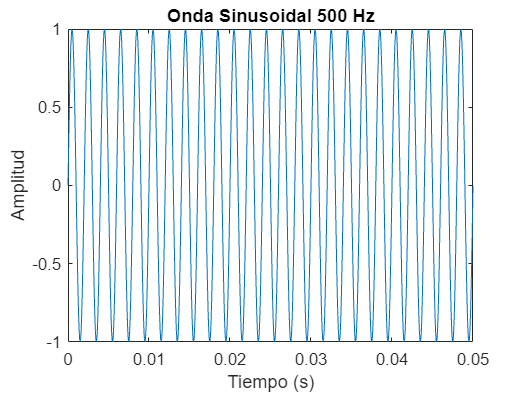

% Definir parámetros de la onda sinusoidal
frecuencia = 500;       % Frecuencia en Hz
% Calcular la onda sinusoidal
senal = sin(2 * pi * frecuencia * t1);
% Graficar la onda sinusoidal
plot(t1, senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Onda Sinusoidal 500 Hz');

## Interpolación

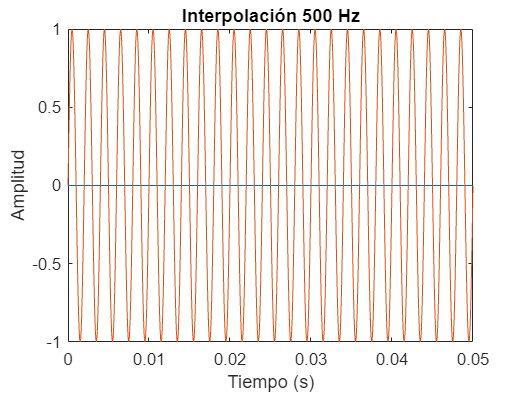

Fs = 200; 
suma = zeros(1,801);
frecuencia = 500; 
%%%%%%%%%%%%%%%%%%%%%%INTERPOLACION%%%%%%%%%%%%%%
for i = 1:Fs
   x = sin(2 * pi * frecuencia * (i/Fs)); 
   h = t1 -(i/Fs);   
   g = sinc(Fs * h); 
   aux = x*g;
   suma = aux + suma;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Graficar la onda sinusoidal
plot(t1, suma);
hold on; 
plot(t1,senal);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Interpolación 500 Hz');
hold off;